sample_values = modified_gaussian_inverse_cdf(rand(1,1e3),6/10,.07);
pdf = @(x) modified_gaussian(x,6/10,.07);

[~,~,palpha_values,pbeta_values] = iterative_classical_profit_from_sample(sample_values);

unique_palpha_values = sort(unique(palpha_values(~isnan(palpha_values))),'descend');
unique_pbeta_values = unique(pbeta_values(~isnan(pbeta_values)));

alpha_values = round(100*unique_palpha_values./(1-unique_palpha_values),1)

alpha_values =   173.7000  156.0000  149.8000


beta_values = round(100*unique_pbeta_values./(1-unique_pbeta_values),1)

beta_values =   121.8000  134.0000  138.7000


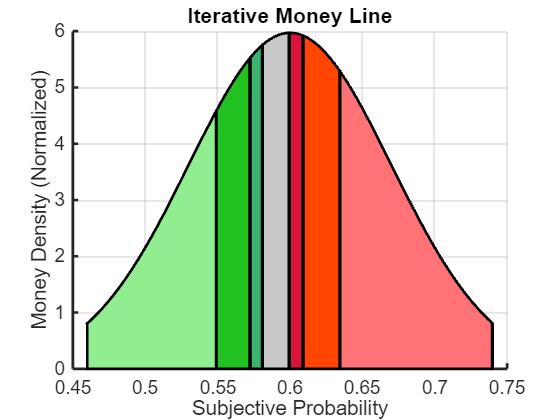


figure
hold on
x_mesh = .46:.001:.74;
y_mesh = modified_gaussian(x_mesh,6/10,.07);

plot(x_mesh,y_mesh,'LineWidth',2,'Color',[0 0 0])
plot([x_mesh(1) x_mesh(1)],[0 pdf(x_mesh(1))],'LineWidth',2,'Color',[0 0 0])
plot([x_mesh(end) x_mesh(end)],[0 pdf(x_mesh(end))],'LineWidth',2,'Color',[0 0 0])
xlabel('Subjective Probability')
ylabel('Money Density (Normalized)')
title('Iterative Money Line')
sexy_plot

focal_colors = {[255,114,118]/255,[255,69,0]/255,[220,20,60]/255};
compliment_colors = {[144,238,144]/255,[34,193,34]/255,[60,179,113]/255};
for index = 1:length(unique_palpha_values)
    if index == 1
        lower_bound = x_mesh(1);
        upper_bound = x_mesh(end);
    else
        lower_bound = unique_pbeta_values(index-1);
        upper_bound = unique_palpha_values(index-1);
    end
   

    % Adding the Red Area
    pa = unique_palpha_values(index);
    xReds = cat(2,pa:.001:upper_bound,flip(pa:.001:upper_bound));
    yReds = cat(2,pdf(pa:.001:upper_bound),zeros(1,length(pa:.001:upper_bound)));
    patch(myAxes,xReds,yReds,focal_colors{index},'LineWidth',2)

    % Adding the Green Area
    pb = unique_pbeta_values(index);
    xGreens = cat(2,lower_bound:.001:pb,flip(lower_bound:.001:pb));
    yGreens = cat(2,pdf(lower_bound:.001:pb),zeros(1,length(lower_bound:.001:pb)));
    patch(myAxes,xGreens,yGreens,compliment_colors{index},'LineWidth',2)
end

% Adding the Gray Area
xGrays = cat(2,pb:.001:pa,flip(pb:.001:pa));
yGrays = cat(2,pdf(pb:.001:pa),zeros(1,length(pb:.001:pa)));
patch(myAxes,xGrays,yGrays,[200 200 200]/255,'LineWidth',2)